clear all; clc;
s = tf('s');

% Funcion en lazo directo
Gld = tf([3],[1,2,5])

Gld =
 
        3
  -------------
  s^2 + 2 s + 5
 
Continuous-time transfer function.




% Funcion en Lazo cerrado
Glc =feedback(Gld,1)

Glc =
 
        3
  -------------
  s^2 + 2 s + 8
 
Continuous-time transfer function.




% Estructura PID encontrada por medio de Estructura Fija
Kp=59.841;
Ti=0.486;
Td=0.185;
PID = Kp*tf([Ti*Td, Ti,1],[Ti,0])

PID =
 
  5.38 s^2 + 29.08 s + 59.84
  --------------------------
           0.486 s
 
Continuous-time transfer function.



Prefilter = 10.98*tf([1],[1,6.365,10.98])

Prefilter =
 
          10.98
  ---------------------
  s^2 + 6.365 s + 10.98
 
Continuous-time transfer function.



hold on

% Estructura PID por asignación de polos, IMC 
A=4.2033;
B=5.867;

Gc = tf((s^2+2*s+5)*A/(s*(s+B)));
Glcc=feedback(Gc*Gld,1)

Glcc =
 
                                   
        12.61 s^2 + 25.22 s + 63.05
                                   
  ----------------------------------------
                                          
  s^4 + 7.867 s^3 + 29.34 s^2 + 54.55 s   
                                          
                                   + 63.05
                                          
 
Continuous-time transfer function.




%asignando un polo no dominante
Gcc = tf((s^2+2*s+5)*A*(s+6.7)/(s*(s+B)))

Gcc =
 
  4.203 s^3 + 36.57 s^2 + 77.34 s + 140.8
  ---------------------------------------
               s^2 + 5.867 s
 
Continuous-time transfer function.



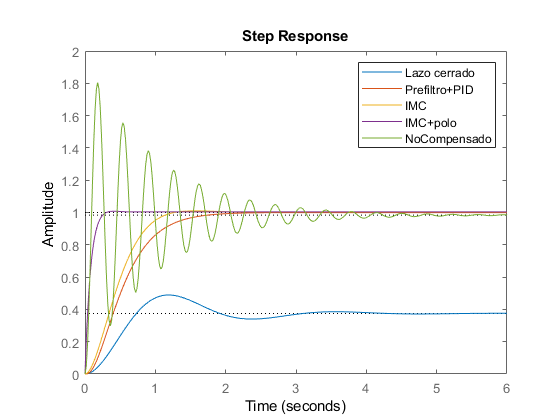


% step(2.65*Glc);  %Grafica sin controlador
step(Glc);
step(Prefilter*feedback(PID*Gld,1))   %Grafica con PID estructura fija
step(Glcc); %Grafica por IMC
step(feedback(Gcc*Gld,1)) %IMC con polo no dominante adicional
legend('Lazo cerrado', 'Prefiltro+PID','IMC','IMC+polo')

%paso 1
NoCompensado = feedback(Gld*100,1);
step(NoCompensado);


hold off